train = readtable("2024-2-artificial-intelligence-001-final-exam-q-3\train.csv");
test = readtable("2024-2-artificial-intelligence-001-final-exam-q-3\test.csv");

train.id = [];
y_train = train.label;
train.label = [];
test.id= [];

y_train = categorical(y_train)

y_train = 5000×1 categorical 배열
     6 
     6 
     0 
     4 
     4 
     0 
     8 
     3 
     3 
     7 
     4 
     2 
     4 
     6 
     8 
     0 
     3 
     3 
     2 
     4 
     7 
     1 
     4 
     2 
     5 
     3 
     5 
     8 
     7 
     6 


% 5000 * 3072 -> 32 * 32 * 3 * 5000
train_array = table2array(train);

% 5000 * 1024 -> 32 * 32 * 1 * 5000
train_R = train_array(:,1:1024);
train_G = train_array(:,1025:2048);
train_B = train_array(:,2049:3072);

train_R_permute = permute(train_R,[2 1]);
train_R_reshape = reshape(train_R_permute,[32 32 1 5000]);
train_R_data = permute(train_R_reshape,[2 1 3 4]);
size(train_R_data)

ans =           32          32           1        5000


train_G_permute = permute(train_G,[2 1]);
train_G_reshape = reshape(train_G_permute,[32 32 1 5000]);
train_G_data = permute(train_G_reshape,[2 1 3 4]);
size(train_G_data)

ans =           32          32           1        5000


train_B_permute = permute(train_B,[2 1]);
train_B_reshape = reshape(train_B_permute,[32 32 1 5000]);
train_B_data = permute(train_B_reshape,[2 1 3 4]);
size(train_B_data)

ans =           32          32           1        5000


train_data = cat(3,train_R_data,train_G_data,train_B_data);
size(train_data)

ans =           32          32           3        5000


partition = cvpartition(height(y_train),'holdout',0.2);

train_idx = training(partition);
val_idx = ~train_idx;

x_train_split = train_data(:,:,:,train_idx);
y_train_split = y_train(train_idx);

x_val = train_data(:,:,:,val_idx);
y_val = y_train(val_idx);
size(x_val)

ans =           32          32           3        1000



valData = {x_val,y_val}

valData = 1×2 cell 배열
    {32×32×3×1000 double}    {1000×1 categorical}


opts = trainingOptions("sgdm","Plots","training-progress","Metrics","accuracy",...
    "MaxEpochs",20,"InitialLearnRate",0.0001,...
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",10,"ValidationData",valData,"ValidationFrequency",10,...
    "OutputNetwork","best-validation");

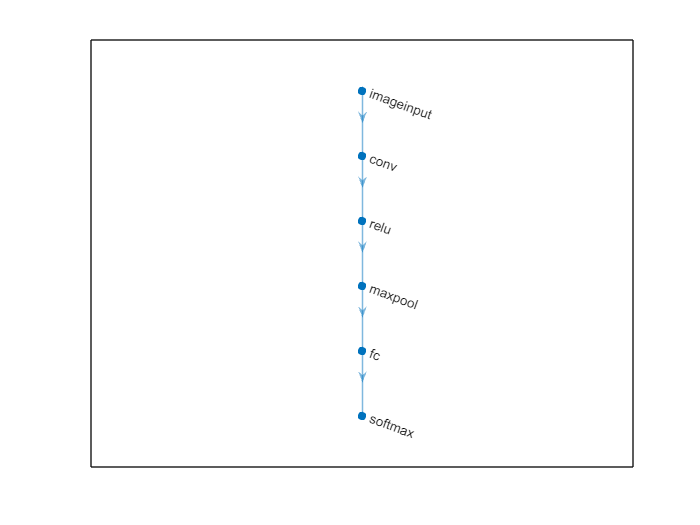

net = dlnetwork;
tempNet = [
    imageInputLayer([32 32 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    fullyConnectedLayer(10,"Name","fc")
    softmaxLayer("Name","softmax")];
net = addLayers(net,tempNet);

% 헬퍼 변수 정리
clear tempNet;

net = initialize(net);
plot(net);

classes = categories(y_train)

classes = 10×1 cell 배열
    {'0'}
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}
    {'8'}
    {'9'}


size(train_data)

ans =           32          32           3        5000


net_Q3 = trainnet(x_train_split,y_train_split,net,"crossentropy",opts)

net_Q3_2 =   dlnetwork - 속성 있음:

         Layers: [9×1 nnet.cnn.layer.Layer]
    Connections: [8×2 table]
     Learnables: [6×3 table]
          State: [0×3 table]
     InputNames: {'imageinput'}
    OutputNames: {'softmax'}
    Initialized: 1

  요약 보기(summary 참조).


test_array = table2array(test);

% 5000 * 1024 -> 32 * 32 * 1 * 5000
test_R = test_array(:,1:1024);
test_G = test_array(:,1025:2048);
test_B = test_array(:,2049:3072);

test_R_permute = permute(test_R,[2 1]);
test_R_reshape = reshape(test_R_permute,[32 32 1 1000]);
test_R_data = permute(test_R_reshape,[2 1 3 4]);
size(test_R_data)

ans =           32          32           1        1000



test_G_permute = permute(test_G,[2 1]);
test_G_reshape = reshape(test_G_permute,[32 32 1 1000]);
test_G_data = permute(test_G_reshape,[2 1 3 4]);
size(test_G_data)

ans =           32          32           1        1000



test_B_permute = permute(test_B,[2 1]);
test_B_reshape = reshape(test_B_permute,[32 32 1 1000]);
test_B_data = permute(test_B_reshape,[2 1 3 4]);
size(test_B_data)

ans =           32          32           1        1000




test_data = cat(3,test_R_data,test_G_data,test_B_data);
size(test_data)

ans =           32          32           3        1000


scores = minibatchpredict(net_Q3,test_data);
[testPred,score] = scores2label(scores,classes);

test_y = readtable("2024-2-artificial-intelligence-001-final-exam-q-3\sample_submission.csv");

test_y.label = testPred;
writetable(test_y,"2024-2-artificial-intelligence-001-final-exam-q-3\sample_submission.csv");